# Demo 2: YOLOv11 Object Detection & Segmentation

Load a YOLOv11 LiteRT model and run detection + segmentation on an image.

## Load and Display a Test Image

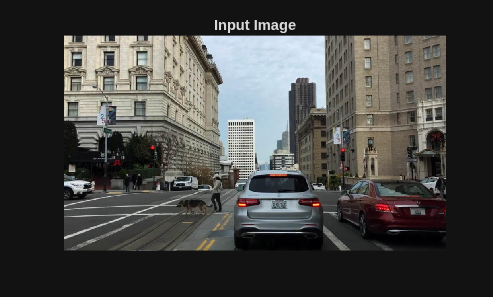

I = imread("downtownScene.jpg");
imshow(I);
title("Input Image");

## Run Inference

out = yolo_segment(I);


Loading the model. This may take a few minutes.


## Display Results

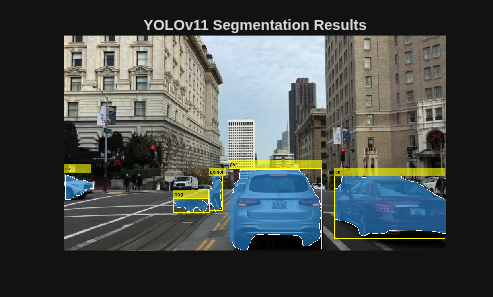

figure;
imshow(out);
title("YOLOv11 Segmentation Results");

## Generate MEX (Code Generation)

cfg = coder.config("mex");
codegen -config cfg yolo_segment -args {I} -report;

Code generation successful: View report



fprintf('MEX function generated successfully.\n');

MEX function generated successfully.


## Run Generated MEX

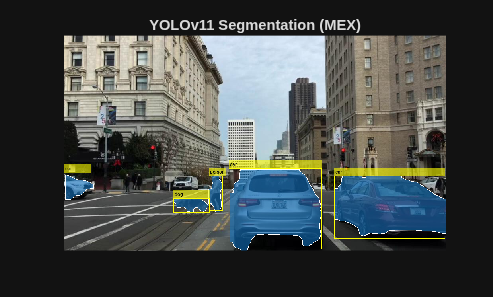

out_mex = yolo_segment_mex(I);
figure;
imshow(out_mex);
title("YOLOv11 Segmentation (MEX)");